  %% Load data
    root_folder = 'E:\Project_A\project_share\Project_A_image_cross';
    train_folder = 'train\left';
    class_folder_left = 'class\left';
    class_folder_right = 'class\right';
    class_folder_straight = 'class\straight';
    class_folder_U = 'class\U';
    
    full_path_train = fullfile(root_folder, train_folder);
    full_path_class_left = fullfile(root_folder, class_folder_left);
    full_path_class_right = fullfile(root_folder, class_folder_right);
    full_path_class_straight = fullfile(root_folder, class_folder_straight);
    full_path_class_U = fullfile(root_folder, class_folder_U);
    imds = imageDatastore(full_path_train, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames'); 
   %% split train & validation
    [imdsTrain,imdsValidation] = splitEachLabel(imds,0.875);

%% Load pretrained network
net = alexnet;
analyzeNetwork(net)
layersTransfer = net.Layers(1:end-3); % replace final layers, last 3 layers are configured for 1000 classes   
inputSize = net.Layers(1).InputSize

inputSize =    227   227     3


%% Data for classification
    imdsTest_left = imageDatastore(full_path_class_left, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
    imdsTest_right = imageDatastore(full_path_class_right, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
    imdsTest_straight = imageDatastore(full_path_class_straight, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
    imdsTest_U = imageDatastore(full_path_class_U, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
    augimdsTest_left = augmentedImageDatastore(inputSize,imdsTest_left,"ColorPreprocessing","gray2rgb");
    augimdsTest_right = augmentedImageDatastore(inputSize,imdsTest_right,"ColorPreprocessing","gray2rgb");
    augimdsTest_straight = augmentedImageDatastore(inputSize,imdsTest_straight,"ColorPreprocessing","gray2rgb");
    augimdsTest_U = augmentedImageDatastore(inputSize,imdsTest_U,"ColorPreprocessing","gray2rgb");



numClasses = numel(categories(imdsTrain.Labels))

numClasses = 5

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];
pixelRange = [-30 30];


imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore(inputSize,imdsTrain, ...
    'DataAugmentation',imageAugmenter,'ColorPreprocessing','gray2rgb');
augimdsValidation = augmentedImageDatastore(inputSize,imdsValidation,"ColorPreprocessing","gray2rgb");

%% Training options
miniBatchSize = 30;
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-3, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');
    options.ExecutionEnvironment = 'gpu';
   


## Train network

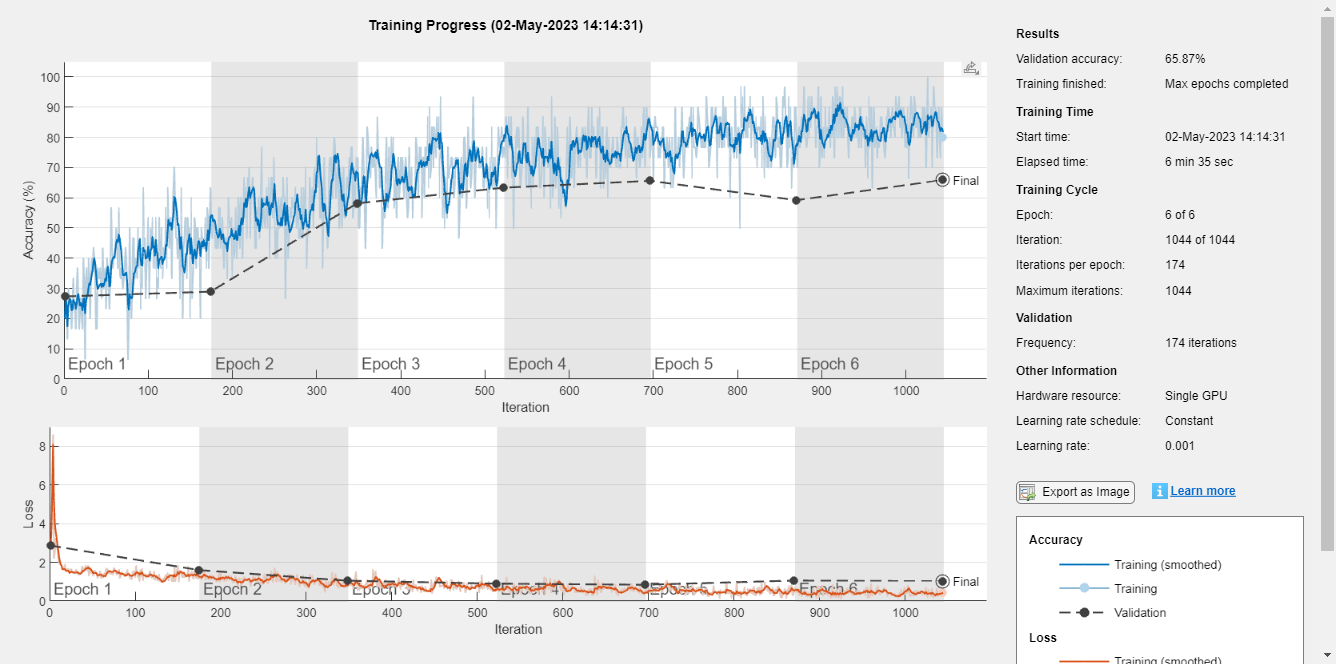

netTransfer = trainNetwork(augimdsTrain,layers,options);

## Classify validation images

[YPred,scores] = classify(netTransfer,augimdsValidation);
YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.6587

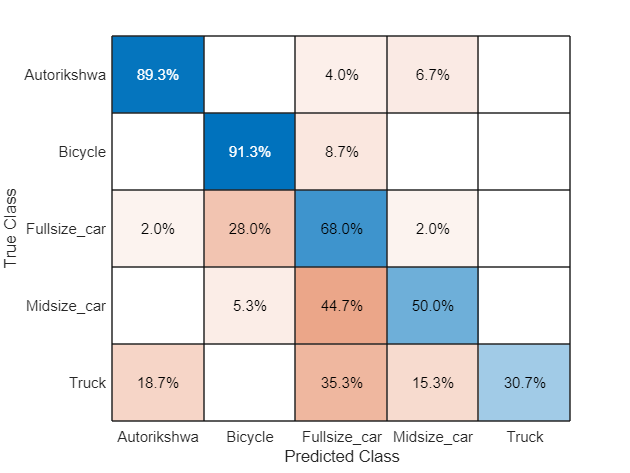

confusionchart(YValidation,YPred,'Normalization','row-normalized')

## Classify test images

    %% CLassify
    
    
    [YPred_left,probs_left] = classify(netTransfer,augimdsTest_left);
    [YPred_right,probs_right] = classify(netTransfer,augimdsTest_right);
    [YPred_straight,probs_straight] = classify(netTransfer,augimdsTest_straight);
    [YPred_U,probs_U] = classify(netTransfer,augimdsTest_U);
    accuracy_test_left = mean(YPred_left == imdsTest_left.Labels)

accuracy_test_left = 0.7284

    accuracy_test_right = mean(YPred_right == imdsTest_right.Labels)

accuracy_test_right = 0.7485

    accuracy_test_straight = mean(YPred_straight == imdsTest_straight.Labels)

accuracy_test_straight = 0.7679

    accuracy_test_U = mean(YPred_U == imdsTest_U.Labels)

accuracy_test_U = 0.7354

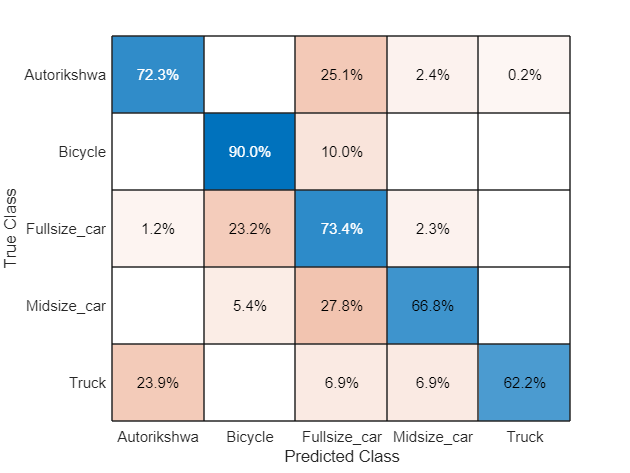

    confusionchart(imdsTest_left.Labels,YPred_left,'Normalization','row-normalized')

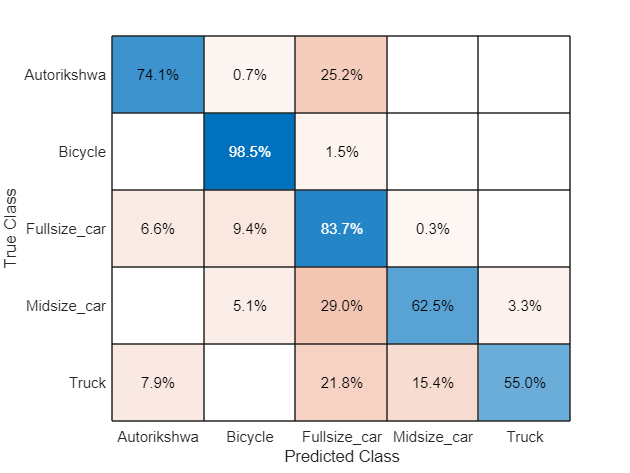

    confusionchart(imdsTest_right.Labels,YPred_right,'Normalization','row-normalized')

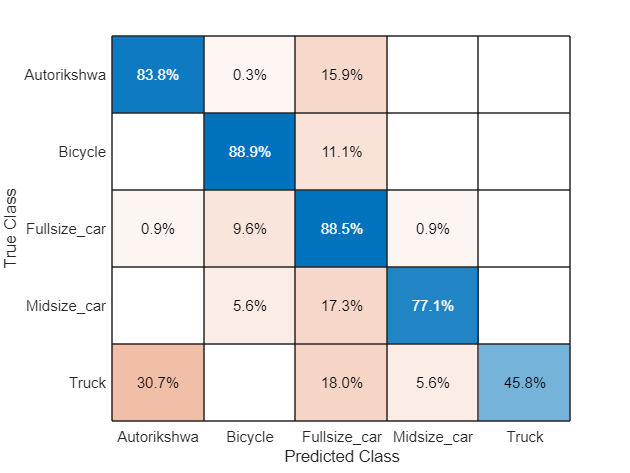

    confusionchart(imdsTest_straight.Labels,YPred_straight,'Normalization','row-normalized')

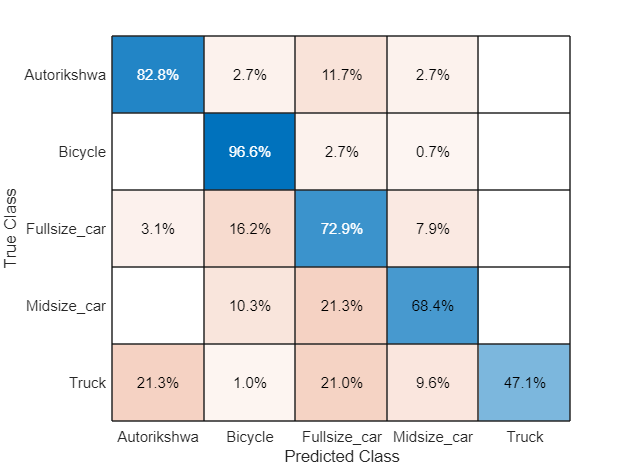

    confusionchart(imdsTest_U.Labels,YPred_U,'Normalization','row-normalized')

    F1_left  = calculateF1score(imdsTest_left.Labels,YPred_left)
    F1_right = calculateF1score(imdsTest_right.Labels,YPred_right)
    F1_straight = calculateF1score(imdsTest_straight.Labels,YPred_straight)
    F1_U = calculateF1score(imdsTest_U.Labels,YPred_U)